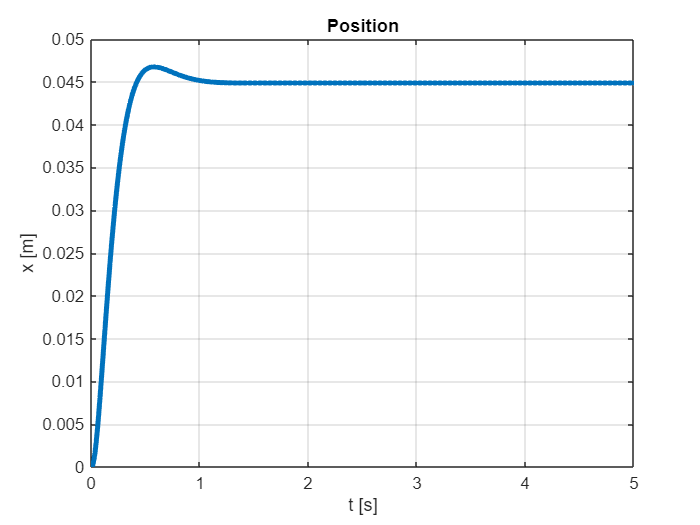

run("wheel/wheel_parameters.m")
% Initial state
X0 = [0; 0; 5*pi/180; 0];

% SIMULINK
% Regulator (Inner Loop)
Kp_t = -300;
Td_t = -20;
Ti_t = 0;

% Regulator (Outer Loop)
Kp_v = 0.1;
Td_v = 0;
Ti_v = 0;


Tsim = 5;
%  (vref = 0), keep stable position
t = 0:0.001:5;
v_ref = 0 * ones(size(t));
input_signal = [t' v_ref'];
out = sim("wheel/wheel_robot_sim.slx");

x_v = out.simout.signals.values(:,1); 
dx_v = out.simout.signals.values(:,2); 
theta_v = out.simout.signals.values(:,3);
dtheta_v = out.simout.signals.values(:,4);
t_v = out.tout;

% x
figure;
plot(t_v, x_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('x [m]');
title('Position');
grid on;

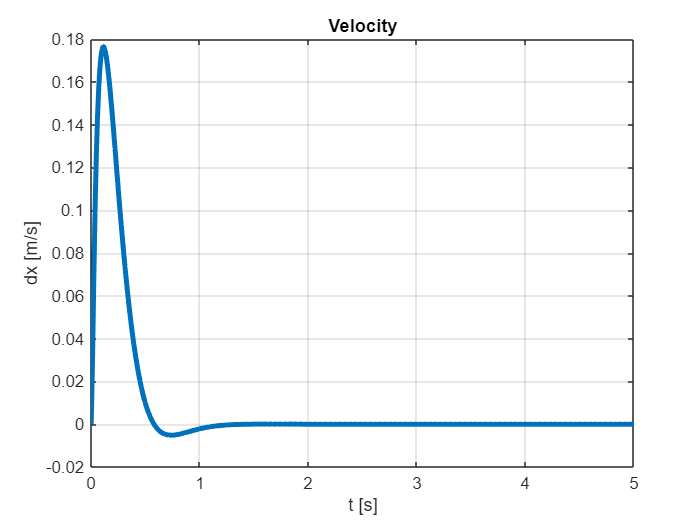


% dx
figure;
plot(t_v, dx_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('dx [m/s]');
title('Velocity');
grid on;

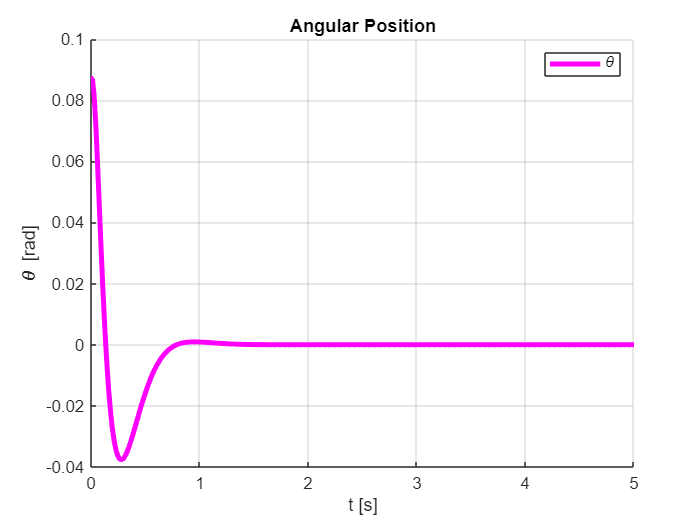


% theta
figure;
hold on;
plot(t_v, theta_v, "LineWidth", 3,"Color","magenta","DisplayName","\theta");
% Extract theta_ref
%theta_ref = out.simout1.signals.values;
%plot(t_v, theta_ref, 'LineWidth', 2,"DisplayName","\theta_{ref}","LineStyle","--");
xlabel('t [s]');
ylabel('\theta [rad]');
title('Angular Position');
legend('show');
grid on;

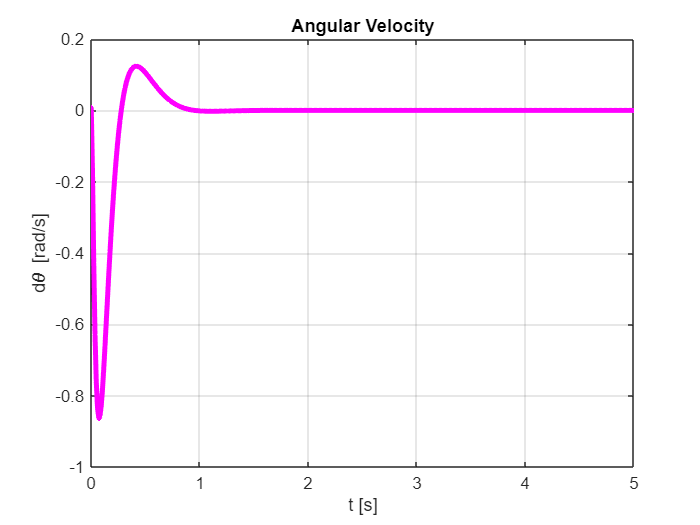


% dtheta
figure;
plot(t_v, dtheta_v, "LineWidth", 3,"Color","magenta");
xlabel('t [s]');
ylabel('d\theta [rad/s]');
title('Angular Velocity');
grid on;